# Segmentación de imágenes

clear all
close all
clc

**Carga de imagen**

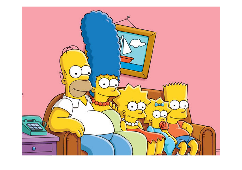

sim = imread('simpsons.png');
figure(1)
imshow(sim)

size(sim)

ans =    600   800     3


seg = zeros(size(sim));
dsim = double(sim);

**Inicia Segmentación**

[imax,jmax,kmax]=size(dsim)

imax = 600

jmax = 800

kmax = 3

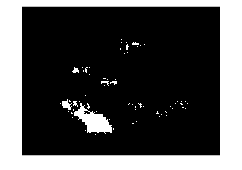

seg2 = seg;
for x = 1:imax
    for y= 1:jmax
        if dsim(x,y,1)>254 && dsim(x,y,2)>254 && dsim(x,y,3)>254
            seg2(x,y,1)=dsim(x,y,1);
            seg2(x,y,2)=dsim(x,y,2);
            seg2(x,y,3)=dsim(x,y,3);
        end
    end
end
imshow(uint8(seg2))